close all; clear; clc;
Resultspath = "results\";
% fclose all;

subpaths = dir();
subpaths = subpaths(3:end);


for i = 1:length(subpaths)
    if(subpaths(i).name(1) == "_")
        
    end
end

subpaths

subpaths = 10×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


subpaths = subpaths(1:2)

subpaths = 2×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum



target_paths = [];

for i = 1:length(subpaths)
    subsubpaths = dir(subpaths(i).name);
    subsubpaths = subsubpaths(3:end);
    for j = 1:length(subsubpaths)
        if ~strcmp(subsubpaths(j).name,'Old')
            subsubsubpath = dir([subpaths(i).name,'/',subsubpaths(j).name]);
            for k = 1:length(subsubsubpath)
                if (~strcmp(subsubsubpath(k).name,'.') && ~strcmp(subsubsubpath(k).name,'..') && subsubsubpath(k).isdir)
                    for l = 1:length(subsubsubpath(k))
                        target_paths = [target_paths;string([subpaths(i).name,'/',subsubpaths(j).name,'/',subsubsubpath(k).name])];
                    end
                end
            end
        end
    end
end

target_paths

target_paths = 38×1 string array
    "DQN/N1_Layers/DQN_1_128_1_001_2e-03_099_1e+00_099"
    "DQN/N1_Layers/DQN_1_128_1_001_2e-03_099_1e-01_099"
    "DQN/N1_Layers/DQN_1_128_1_001_2e-03_099_1e-02_099"
    "DQN/N2_Layers/DQN_2_128_1_001_2e-03_099_1e-01_099"
    "DQN/N2_Layers/DQN_2_128_1_001_2e-03_099_1e-02_099"
    "DQN/N2_Layers/DQN_2_128_1_001_2e-03_099_1e-05_099"
    "DQN/N4_Layers/DQN_4_128_1_001_2e-02_099_1e-01_099"
    "DQN/N4_Layers/DQN_4_128_1_001_2e-02_099_1e-02_099"
    "DQN/N4_Layers/DQN_4_128_1_001_2e-02_099_1e-03_099"
    "DQN/N4_Layers/DQN_4_128_1_001_2e-03_099_1e-03_099"
    "DQN/N4_Layers/DQN_4_128_1_001_2e-03_099_1e-04_099"
    "DQN/N4_Layers/DQN_4_128_1_001_2e-03_099_1e-05_099"
    "DQN/N4_Layers/DQN_4_128_1_001_4e-03_099_1e-01_099"
    "DQN/N4_Layers/DQN_4_128_1_001_4e-03_099_1e-02_099"
    "DQN/N4_Layers/DQN_4_128_1_001_4e-03_099_1e-03_099"
    "DQN/N6_Layers/DQN_6_128_1_001_2e-03_099_1e+00_099"
    "DQN/N6_Layers/DQN_6_128_1_001_2e-03_099_1e-01_099"
    "DQN/N6_Lay

Unrecognized function or variable 'files'.

f_data = [];

for i = 1:length(target_paths)
    fname = target_paths(i)+"/data.json";
    json = fileread(fname);
    temp = jsondecode(json);
    temp.Name = extractBetween(fname,'DuelingDQN_','/data.json');
    temp.Name = "DuelingDQN_"+temp.Name;
    if isempty(temp.Name)
        temp.Name = extractBetween(fname,'DQN_','/data.json');
        temp.Name = "DQN_"+temp.Name;
    end
    f_data = [f_data temp];
end

f_data

f_data = 1×38 struct array with fields:
    arch
    n_layers
    episodes_trained
    last_avg_score
    batch_size
    exploration_threshold
    exploration_threshold_min
    exploration_decay
    discount_factor
    learning_rate
    learning_rate_decay
    episodes
    scores
    events
    avg_scores
    avg_scores20
    exploration
    avg_scores100
    Name



% fields = fieldnames(files);
% 
% for p = 1:length(fields)
%     if isempty(files.(fields{p}))
%         continue;
%     end
%     
%     [~, reindex] = sort( str2double( regexp( {files.(fields{p}).name}, '\d+', 'match', 'once' )));
%     subpaths = files.(fields{p});
%     subpaths = subpaths(reindex);
%     
% %     subpaths = files.(fields{p});
%     
%     nFiles = length(files.(fields{p}));
%     
%     for i = 1:nFiles
%         fname = Resultspath+subpaths(i).path+subpaths(i).name+"\data.json";
%         json = fileread(fname);
%         temp = jsondecode(json);
%         temp.Name = [char(subpaths(i).path),char(temp.Name)];
%         f_data = [f_data temp];
%     end
% end

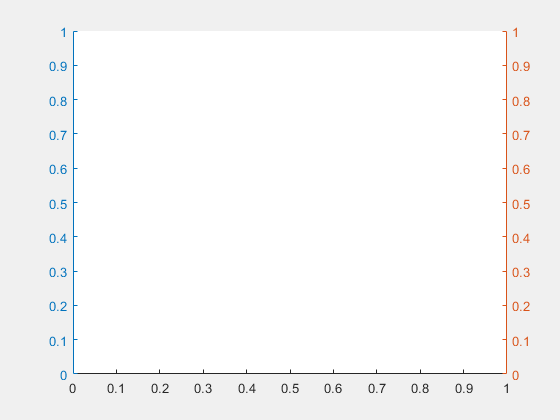

Unrecognized field name "NumberOfEpochs".

close all
f = figure;
set(f,'Visible','on');
hold on

c = hsv(length(f_data));


for i = 1:length(f_data)
    yyaxis right
    tick_size = f_data(i).NumberOfEpochs/f_data(i).NumberOfSteps;
    plot(0:tick_size:f_data(i).NumberOfEpochs,[0;f_data(i).MeanClassAccuracy],'Color',c(i,:),'Marker', 'none','LineStyle','-','Tag',strcat(f_data(i).Name,'_r'));
%     if strcmp(f_data(i).Name(end-1:end),'et')
%         plot([0:tick_size:150],[0;f_data(i).MeanClassAccuracy]','Color',c(i,:),'Marker', 'none','LineStyle','-','Tag',strcat(f_data(i).Name,'_r'));
%     else
%         
%     end
    yyaxis left
    plot(f_data(i).Loss_Epoch(:,1),f_data(i).Loss_Epoch(:,2),'Color',c(i,:),'Marker', 'none','LineStyle','-','Tag',strcat(f_data(i).Name,'_l'));
end








interactiveLegend(f,{f_data(:).Name});

yyaxis left
ylabel('Loss')

yyaxis right
xlabel('Epoch')
ylabel('Mean Class Accuracy')
xlim('auto')
ylim('auto')
ax = gca;
ticks = [0:20:60,(60+5/2):5/2:ax.YTick(end)];
ax.YTick = ticks;
ax.XTick = 0:10:ax.XTick(end);
yyaxis right

% Grids

xlims = [0,ax.XTick(end)];
ylims = [0,ax.YTick(end)];
for i = xlims(1):10:xlims(2)
    for j = ticks
        patch(xlims,[1,1]*j,'k','Marker', 'none','LineStyle','-','edgealpha',0.005);
        patch([1,1]*i,ylims,'k','Marker', 'none','LineStyle','-','edgealpha',0.005);
    end
end

